clc; clear;
% First order filter
FirstOrder=tf(1,[1.061e-3 1]);
bode(FirstOrder);

% Third order filter
Order1=tf(1,[1.061e-3 1]);
Order2=tf(1,[1.061e-3*1.061e-3 1.061e-3 1]);
ThirdOrder=Order1*Order2;
bode(ThirdOrder);


% Fifth order filter
Order11=tf(1,[1.061e-3 1]);
Order22=tf(1,[1.061e-3*1.061e-3 1.061e-3*0.618 1]);
Order222=tf(1,[1.061e-3*1.061e-3 1.061e-3*1.618 1]);
FifthOrder=Order11*Order22*Order222;
bode(FifthOrder);
disp(FifthOrder);

  tf with properties:

       Numerator: {[0 0 0 0 0 1]}
     Denominator: {[1.3445e-15 4.1008e-12 6.2537e-09 5.8942e-06 0.0034 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



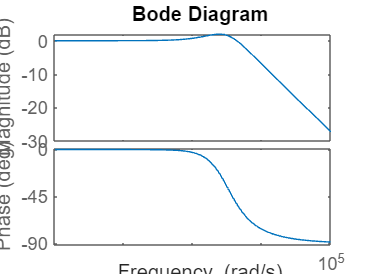

clc; clear;
% PI controller
cont=tf([4.3464 9818.5176],[1 0]);
plant=tf([1],[0.001 0.1]);
G=cont*plant;
cltf=G/(1+G);
bode(cltf);